clc
clear all

load("opt_truncated_mat_files\DOA.mat")
load("opt_truncated_mat_files\pressure.mat")

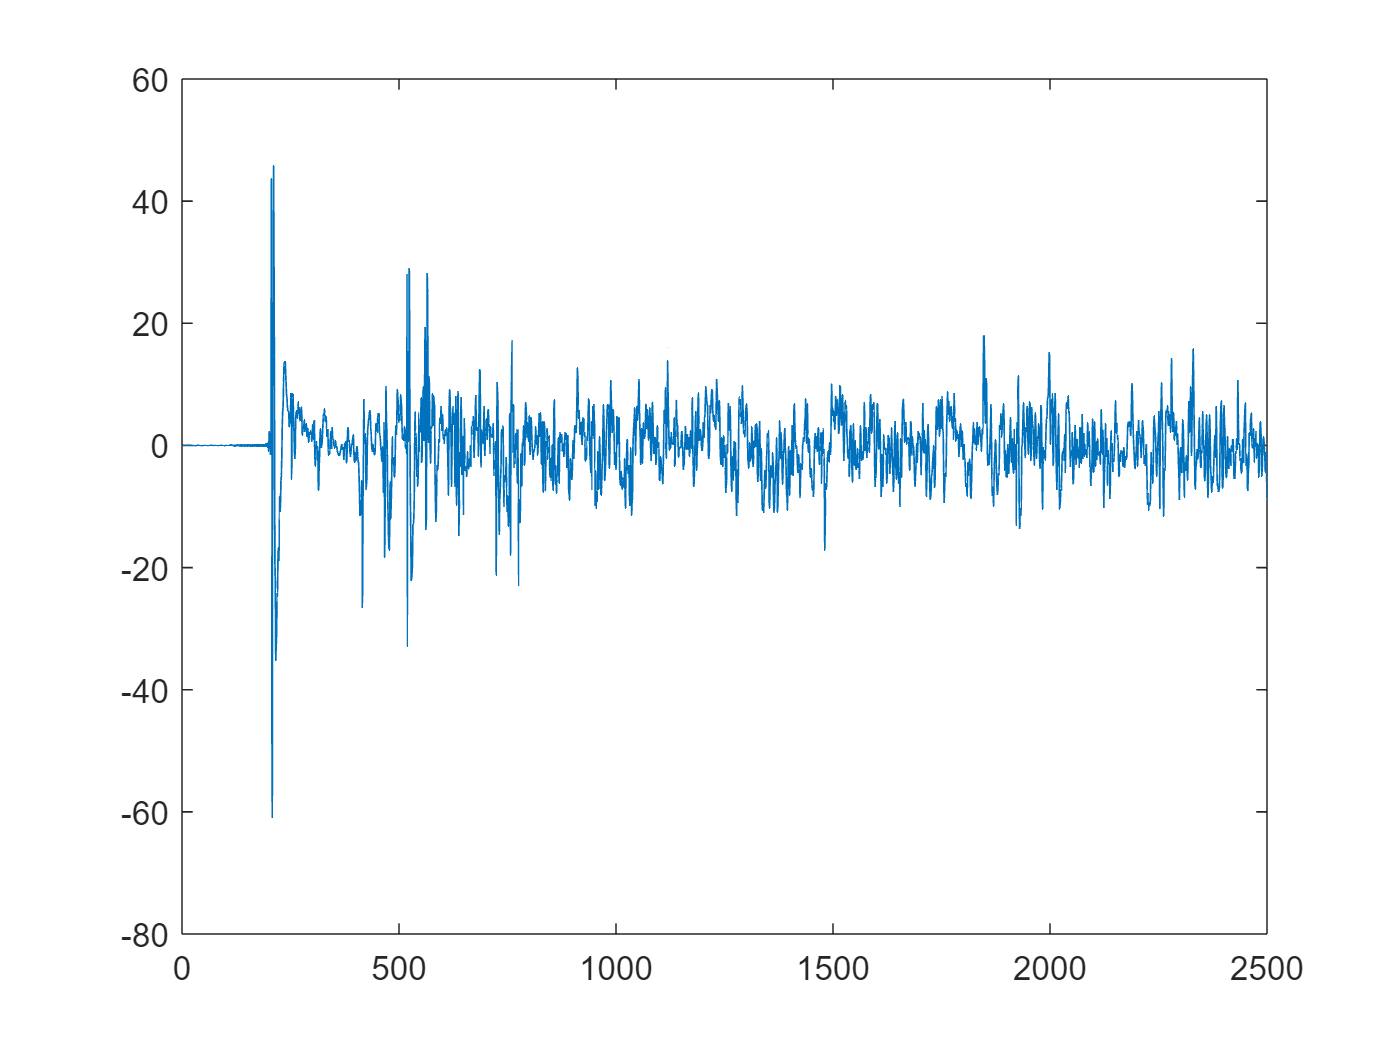

plot(P{1,1})

start_signal = 200;
length_signal = 100;
end_signal = start_signal + length_signal;

DOA1 = DOA{1,1}(start_signal:end_signal,:);
P1 = P{1,1}(start_signal:end_signal);
DOA3 = DOA{3,1}(start_signal:end_signal,:);
P3 = P{3,1}(start_signal:end_signal);

% 0 = only negative pressure values
% 1 = only positive pressure values
% 2 = both pos&neg pressure values
positive_values = 2;

if positive_values == 1
    P1(P1 < 0) = 0;
    P3(P3 < 0) = 0;
elseif positive_values == 0
    P1(P1 > 0) = 0;
    P3(P3 > 0) = 0;
    P1 = abs(P1);
    P3 = abs(P3);
elseif positive_values == 2
    P1 = abs(P1);
    P3 = abs(P3);
end

norm(P1,1)

ans = 916.5986

norm(P3,1)

ans = 1.0211e+03

clear DOA
clear P

number_of_discrete_positions = 12;
number_of_speakers = 2;

size_matrix = length(P1);
cost = zeros(size_matrix);

speed_of_sound = 343/48000;

% Optimal transport for measurement 1 and 3
% Cost matrix
for i=1:size_matrix
    for j=1:size_matrix
        cost(j,i) = power(norm((DOA1(i,1:3)*speed_of_sound*i) - (DOA3(j,1:3)*speed_of_sound*j)), 2);
    end
end

% Partial optimal transport matrix extend

distance_between_measurements = 0.4; % Distance between measurement 1 and 3 -> 40cm
epsilon = 1.05*power(norm(distance_between_measurements), 2);% increasing to 1.1-1.5 provide tolerance for imprecision

column = epsilon*ones(size_matrix,1); % Maybe infinity will cause an error
row = transpose(column);

cost_extended = [cost column; row Inf];

% See namegiving in paper RIR interpolation
a = P1;
b = P3;
a(a<0) = 0;
b(b<0) = 0;

% Check which solver is selected
cvx_solver

   Name     Status             Version   Location
--------------------------------------------------------
   SDPT3                       4.0       {cvx}\sdpt3
   SeDuMi   selected,default   1.3.4     {cvx}\sedumi



% Select sedumi solver if not yet selected
cvx_solver sedumi

% Save preferences for solver
cvx_save_prefs

Saving prefs...done.


% Partial Optimal Transport

cvx_begin
    cvx_precision low
    variable T_bar(size_matrix+1,size_matrix+1) nonnegative
    variable sig
    to_minimize = cvx(zeros(size_matrix+1,size_matrix+1));

    %T_bar(size_matrix+1,size_matrix+1) = 0;

    a_bar = [a ; norm(b,1) - sig];
    b_bar = [b ; norm(a,1) - sig];

    for i=1:size_matrix
        for j=1:size_matrix
            if i ~= size_matrix+1 && j ~= size_matrix+1
                to_minimize(i,j) = T_bar(i,j)*cost_extended(i,j);
            else
                to_minimize(i,j) = 0;
            end
        end
    end

    minimize( sum(sum(to_minimize)))
    subject to
        sig >= 0
        sig <= norm(a,1)
        sig <= norm(b,1)
        T_bar*ones(size_matrix+1, 1) == a_bar
        transpose(T_bar)*ones(size_matrix+1, 1) == b_bar
        ones(1,size_matrix)*T_bar(size_matrix,size_matrix)*ones(size_matrix,1) == sig
        T_bar(size_matrix+1,size_matrix+1) == 0

        for i=1:size_matrix+1
            for j=1:size_matrix+1
                T_bar(i,j) >= 0
            end
        end
cvx_end

 
Calling SeDuMi 1.3.4: 21015 variables, 10403 equality constraints
   For improved efficiency, SeDuMi is solving the dual problem.
------------------------------------------------------------
SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Split 204 free variables
eqs m = 10403, order n = 21220, dim = 21220, blocks = 1
nnz(A) = 20809 + 41616, nnz(ADA) = 10403, nnz(L) = 10403
Handling 408 + 0 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.03E-01 0.000
  1 :   6.83E+03 1.02E-01 0.000 0.2533 0.9000 0.9000   0.07  1  1  1.9E+00
  2 :   3.24E+03 4.49E-02 0.000 0.4397 0.9000 0.9000   2.68  1  1  4.2E-01
  3 :   9.83E+02 1.10E-02 0.000 0.2456 0.9000 0.9000   2.81  1  1  4.9E-02
  4 :   8.02E+02 9.39E-03 0.000 0.8522 0.9000 0.9000   1.60  1  1  4.0E-02
  5 :   5.59E+02 7.28E-03 0.000 0.7744 0.9000 0.9000   2.55  1  1  2.3E-02
  6 :   2.82E

disp(sig)

    6.0527



T_ = T_bar;

T_bar = T_

T_bar =     0.0045    0.0040    0.0036    0.0031    0.0027    0.0023    0.0019    0.0017    0.0014    0.0013    0.0011    0.0010    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0063    0.0071    0.0069    0.0064    0.0057    0.0049    0.0042    0.0036    0.0030    0.0026    0.0023    0.0019    0.0016    0.0014    0.0012    0.0011    0.0009    0.0008    0.0007    0.0006    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

for i=1:size_matrix+1
    for j=1:size_matrix+1
        if T_bar(i,j) < 1e-5
            T_bar(i,j) = 0;
        end
    end
end

norm(T_bar)

ans = 165.9185

if positive_values == 1
    save("opt_truncated_mat_files\Tbar_positive.mat", "T_bar")
elseif positive_values == 0
    save("opt_truncated_mat_files\Tbar_negative.mat", "T_bar")
elseif positive_values == 2
    save("opt_truncated_mat_files\Tbar.mat", "T_bar")
end